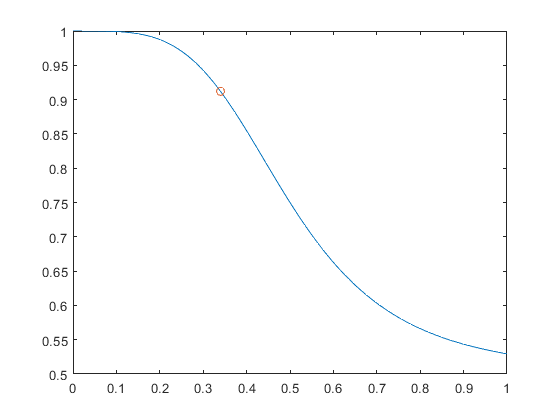

clear;clc

% Generate concentration ranges
c1 = logspace(-3, 0, 24); % 100 log spaced points
%c1 = linspace(0.001, 1, 24);
c2 = c1;
[C1, C2] = meshgrid(c1, c2);



% Define drug characteristics
Emax = 0.5;
E0 = 1;
hill = 4;
EC50 = 0.5;

druga = DrugSingle(Emax, hill, E0, EC50); % Emax, hill, E0, EC50
drugb = DrugSingle(Emax, hill, E0, EC50);
comboab = DrugCombo(druga, drugb);
comboab.Alpha = [100, 100]; % only synergistic potency change
comboab.Beta = 1; % synergistic efficacy change

% Using bend point
k = 4.6805;
bendPoint = EC50*(1/k)^(1/hill);
figure
a = E0;
b = hill;
c = EC50;
d = Emax;
X = linspace(0, 1);
Y = (a-d)./(1 + (X./c).^b) + d;
plot(X,Y)
hold on
plot(bendPoint, (a-d)./(1 + (bendPoint./c).^b) + d,'o')





% Apply drug
Ed = MuSyC(comboab, C1, C2);

% Plot
% 2D Case
figure
%h = surf(C1,C2,Ed,'lines','None');
h = surf(C1,C2,Ed)

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [24×24 double]
           YData: [24×24 double]
           ZData: [24×24 double]
           CData: [24×24 double]

  Show all properties


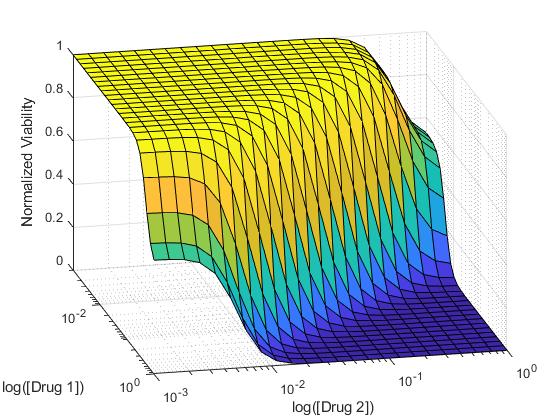

%set(h,'LineStyle','none')
xlabel('log([Drug 1])')
ylabel('log([Drug 2])')
zlabel('Normalized Viability')
set(gca,'xscale','log','yscale','log')
view([77.079 26.316])


figure
%h = surf(C1,C2,Ed,'lines','None');
h = surf(C1,C2,Ed)

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [24×24 double]
           YData: [24×24 double]
           ZData: [24×24 double]
           CData: [24×24 double]

  Show all properties


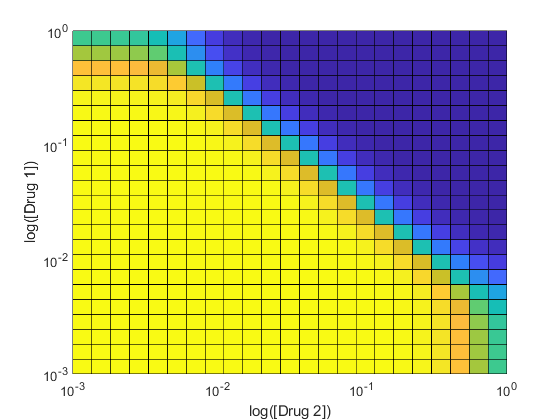

%set(h,'LineStyle','none')
xlabel('log([Drug 1])')
ylabel('log([Drug 2])')
zlabel('Normalized Viability')
set(gca,'xscale','log','yscale','log')
set(gca, 'XDir','reverse')
view([90 90])



figure
%h = surf(C1,C2,Ed,'lines','None');
h = surf(C1,C2,Ed)

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [24×24 double]
           YData: [24×24 double]
           ZData: [24×24 double]
           CData: [24×24 double]

  Show all properties


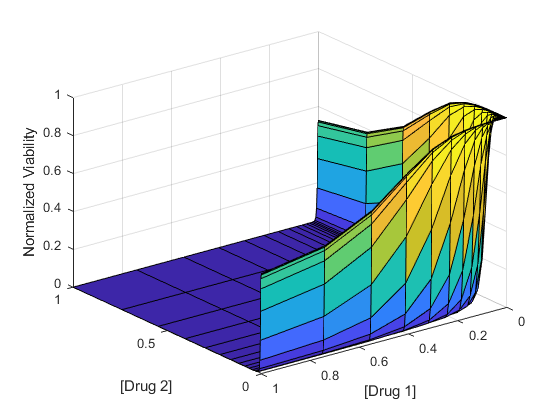

%set(h,'LineStyle','none')
xlabel('[Drug 1]')
ylabel('[Drug 2]')
zlabel('Normalized Viability')
%set(gca,'xscale','log','yscale','log')
axis([0 1 0 1])
set(gca, 'XDir','reverse')

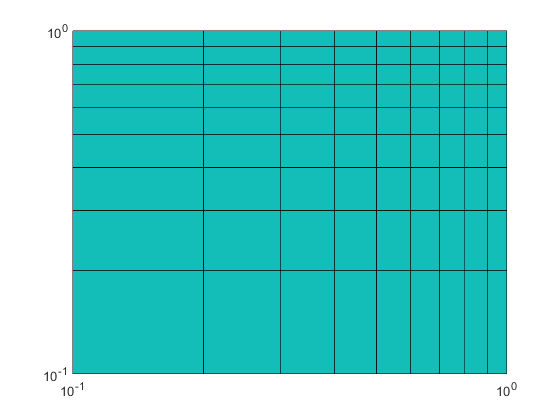

%view([90 90])

figure
x = linspace(0, 1, 11);
y = linspace(0, 1, 11);
[X Y] = meshgrid(x,y);
Z = ones(11,11);
%plot(x,y,'.')
%set(gca,'xscale','log','yscale','log')
surf(X,Y,Z)
set(gca,'xscale','log','yscale','log')
%set(gca, 'XDir','reverse')
view([0,90])

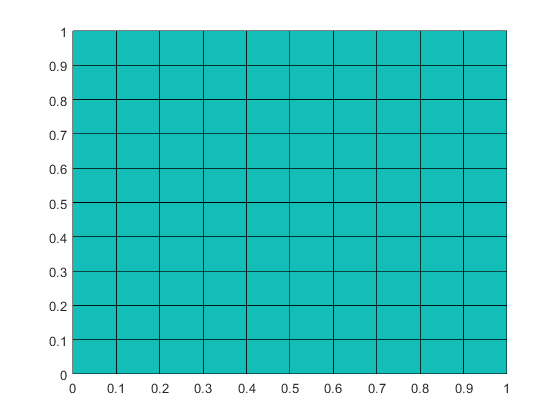

surf(X,Y,Z)
view([0,90])

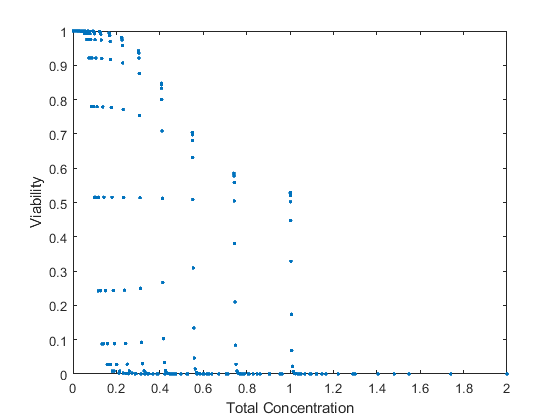



figure
A = reshape(C1+C2,[24*24, 1]);
B = reshape(Ed, [24*24, 1]);
plot(A,B,'.')
xlabel('Total Concentration')
ylabel('Viability')